# SNR effect

In their simulations Frässle et al. use various SNR values. The sensitivity and specificity of the rDCM success seemed to depend on this (see Figures 2-4 in Frässle et al. 2018) so I wondered if the data I was generating was in a region of SNR range that was particularly bad for rDCM.

Turns out this was not something I was directly controlling in my simulations so I asked Frässle how he manipulated it and added his way to my simulations.

In this notebook I first look at how this parameter changes simulated data and then whether changing it improves model inversion.

## Effect on timeseries

How does SNR values change the generated timeseries?

stim_options = get_default_stim_options();

Code used to generate data borrowed from `make_DEM_demo_induced_fmri.m`

T  = stim_options.T;                            
TR = stim_options.TR;                             
n  = stim_options.n;                               

t  = (1:T)*TR;                       
ar_coef = stim_options.ar_coef;
u  = spm_rand_mar(T,n,ar_coef)/4;         

% experimental inputs (Cu = 0 to suppress)
% -------------------------------------------------------------------------
Cu  = ones(n, 1) * 0;
E   = cos(2*pi*TR*(1:T)/24) * 0;

% priors
% -------------------------------------------------------------------------
options.nonlinear  = stim_options.nonlinear;
options.two_state  = stim_options.two_state;
options.stochastic = stim_options.stochastic;
options.centre     = stim_options.centre;
options.induced    = stim_options.induced;

A  = stim_options.A;
B   = zeros(n,n,0);
C  = stim_options.C;
D   = zeros(n,n,0);
pP  = spm_dcm_fmri_priors(A,B,C,D,options);


% true parameters (reciprocal connectivity)
% -------------------------------------------------------------------------

if ( isfield(stim_options,'Tp') )
    pP.A = stim_options.Tp.A;
else
    pP.A = [  0  -.2    0;
             .3    0  -.1;
             0   .2    0];
end

pP.C = eye(n,n); %used by spm_int_J to create states
pP.transit = randn(n,1)/16;

% simulate response to endogenous fluctuations
%==========================================================================

% integrate states
% -------------------------------------------------------------------------
M.f  = 'spm_fx_fmri';
M.x  = sparse(n,5);
U.u  = u + (Cu*E)';
U.dt = TR;
x    = spm_int_J(pP,M,U);

% haemodynamic observer
% -------------------------------------------------------------------------
for i = 1:T
    y(i,:) = spm_gx_fmri(spm_unvec(x(i,:),M.x),[],pP)';
end

% observation noise process
% -------------------------------------------------------------------------
e    = spm_rand_mar(T,n,ar_coef)/4;

Add noise using different SNRs and plot results

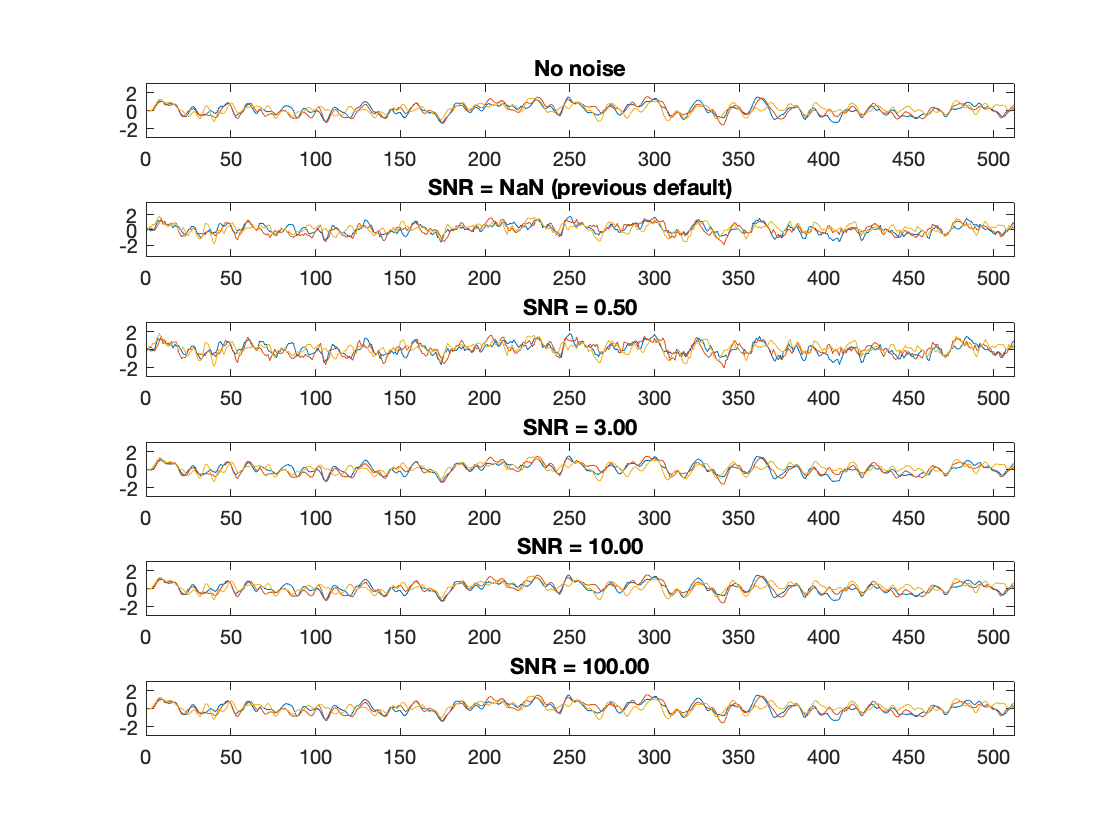

subplot(6,1,1);
plot(y);
axis([0 512 -3 3]);
title("No noise");

subplot(6,1,2);
plot(y + e);
axis([0 512 -3.5 3.5]);
title("SNR = NaN (previous default)");

SNRs = [.5 3 10 100];

for i=1:length(SNRs)
    cur_SNR = SNRs(i);
    cur_r = diag(std(y)/cur_SNR);
    cur_y = y + e*cur_r;
    subplot(6,1,i+2);
    plot(cur_y);
    axis([0 512 -3 3]);
    title(sprintf("SNR = %.02f", cur_SNR));
end

So `SNR=3` seems like a good default in that the noisy signal frrom this SNR value looks similar to the noiseless signal but I still don't understand how this way of using the `SNR` field translates to $\frac{\sigma_{\mathrm{signal}} }{\sigma_{\mathrm{noise}} }$.

## Effect on inversion

clear

Compare 20 datasets of both SNR values

stim_options = get_default_stim_options();
[DCM_SNR3, opt_SNR3] = make_DEM_demo_induced_fmri(stim_options);

stim_options = rmfield(stim_options, 'SNR');

stim_options = struct with fields:
             T: 512
            TR: 2
             n: 3
       ar_coef: 0.5000
             A: [3×3 double]
             C: [3×3 double]
     nonlinear: 0
     two_state: 0
    stochastic: 1
        centre: 1
       induced: 1
            Tp: [1×1 struct]
             a: [3×3 double]
             c: [3×1 double]


[DCM_org, opt_org] = make_DEM_demo_induced_fmri(stim_options);

type = 'r'; % setting to 'r' instead of 's' until bug is fixed
methods = 2; %1 for ridge, 2 for pruning

[out_SNR3, opt_SNR3] = tapas_rdcm_estimate(DCM_SNR3, type, opt_SNR3, methods);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


[out_org, opt_org] = tapas_rdcm_estimate(DCM_org, type, opt_org, methods);


Regression dynamic causal modeling (rDCM) 

Run model inversion
Processing p0: 19/19
Finalize results


out_SNR3.Ep.A

ans =    -0.0436         0         0
    0.1032   -0.1237         0
         0    0.0647   -0.0907


out_org.Ep.A

ans =    -0.0869         0         0
         0   -0.0747         0
         0         0   -0.0793
